%Code used to calculate AIs when we have 9 of those halved-plates aranged

ans =   172789×1 RawDataField array with properties:

          raw: [172789×1 RawDataMap]
         path: 'C:/Users/Jefferis Group/Documents/GitHub/margo_data/18.08-overnight/08-18-2021-18-35-26__Basic_Tracking_1-9_Day1/raw_data/08-18-2021-18-35-26__time.bin'
          fID: 4
          dim: [172789 1]
    precision: 'single'


%in a 3x3 square.
% expmt.data.time
reset(expmt.data.time)

ans =   172789×1 RawDataField array with properties:

          raw: [172789×1 RawDataMap]
         path: 'C:/Users/Jefferis Group/Documents/GitHub/margo_data/18.08-overnight/08-18-2021-18-35-26__Basic_Tracking_1-9_Day1/raw_data/08-18-2021-18-35-26__time.bin'
          fID: 4
          dim: [172789 1]
    precision: 'single'


isattached(expmt.data.time)

ans = logical
   1


interframe_interval = expmt.data.time.raw();
t_elapsed = cumsum(interframe_interval);
% read all centroid data from file
reset(expmt.data.centroid);
centroids = expmt.data.centroid.raw();
a = expmt.meta.roi

a = struct with fields:
           mode: 'grid'
          shape: {9×1 cell}
            vec: [9×4×2 double]
            row: [9×1 double]
            col: [9×1 double]
           grid: [9×1 double]
        corners: [9×4 double]
         bounds: [9×4 double]
        centers: [9×2 double]
    orientation: [9×1 logical]
          tform: {9×1 cell}
             im: [1024×1024 uint8]
              n: 9
         pixIdx: {9×1 cell}
           mask: [1024×1024 logical]
     num_traces: [9×1 double]
       cam_dist: [9×1 double]


%centres of each circle
xcentre1= (a.centers(1,1))

xcentre1 = 195.8264

xcentre2= (a.centers(2,1))

xcentre2 = 524.4751

xcentre3= (a.centers(3,1))

xcentre3 = 861.9054

xcentre4= (a.centers(4,1))

xcentre4 = 181.4563

xcentre5= (a.centers(5,1))

xcentre5 = 514.3628

xcentre6= (a.centers(6,1))

xcentre6 = 846.4709

xcentre7= (a.centers(7,1))

xcentre7 = 174.8035

xcentre8= (a.centers(8,1))

xcentre8 = 525.0073

xcentre9= (a.centers(9,1))

xcentre9 = 849.6642

ycentre1 = (a.centers(1,2))

ycentre1 = 166.0218

ycentre2 = (a.centers(2,2))

ycentre2 = 167.8846

ycentre3 = (a.centers(3,2))

ycentre3 = 172.9407

ycentre4 = (a.centers(4,2))

ycentre4 = 498.1299

ycentre5 = (a.centers(5,2))

ycentre5 = 499.1944

ycentre6 = (a.centers(6,2))

ycentre6 = 505.8472

ycentre7 = (a.centers(7,2))

ycentre7 = 842.2131

ycentre8 = (a.centers(8,2))

ycentre8 = 843.2775

ycentre9 = (a.centers(9,2))

ycentre9 = 836.3586

out = num2cell(centroids, [1 2]); %split into cell array keeping dimensions 1 and 2 together
out = vertcat(out{:}) %concatenate all the cells vertically

out = 1555101×2 single matrix
       NaN       NaN
       NaN       NaN
       NaN       NaN
       NaN       NaN
  186.1622   31.9189
  183.2133   33.1733
  183.6716   34.1343
  185.6154   35.6769
  190.4918   37.6230
  193.5610   38.7317


x = out(:, 1);
y = out(:, 2);
%Here, traces are asigned to the half of a circle where they appear, used
%later on when calculating AIs. The value I am adding and subtracting from
% xcentre and ycentre is not perfect,
%sometimes the area defined by these formulae does not match the area of
%each region perfectly, might need to tweek it a bit.
out(x<xcentre1 & y<ycentre1+160,3)=1

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000


out(x>xcentre1 & x<xcentre2-160 & y<ycentre1+160,3)=2

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000


out(x>xcentre2-160 & x<xcentre2 & y<ycentre2+160,3)=3

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000


out(x>xcentre2 & x<xcentre3-160 & y<ycentre2+160,3)=4

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000


out(x>xcentre3-160 & x<xcentre3 & y<ycentre3+160,3)=5

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000


out(x>xcentre3 & y<ycentre3+160,3)=6

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000



out(x<xcentre4 & y>ycentre1+160 & y<ycentre4+160,3)=7

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000


out(x>xcentre4 & x<xcentre4+160 & y>ycentre1+160 & y<ycentre4+160,3)=8

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000


out(x>xcentre5-160 & x<xcentre5 & y>ycentre2+160 & y<ycentre5+160,3)=9

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000


out(x>xcentre5 & x<xcentre5+160 & y>ycentre2+160 & y<ycentre5+160,3)=10

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000


out(x>xcentre6-160 & x<xcentre6 & y>ycentre3+160 & y<ycentre6+160,3)=11

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000


out(x>xcentre6 & y>ycentre3+160 & y<ycentre6+160,3)=12

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000



out(x<xcentre7 & y>ycentre7-160,3)=13

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000


out(x>xcentre7 & x<xcentre7+160 & y>ycentre7-160,3)=14

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000


out(x>xcentre8-160 & x<xcentre8 & y>ycentre8-160,3)=15

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000


out(x>xcentre8 & x<xcentre8+160 & y>ycentre8-160,3)=16

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000


out(x>xcentre9-160 & x<xcentre9 & y>ycentre9-160,3)=17

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000


out(x>xcentre9 & y>ycentre9-160,3)=18

out = 1555101×3 single matrix
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
       NaN       NaN         0
  186.1622   31.9189    1.0000
  183.2133   33.1733    1.0000
  183.6716   34.1343    1.0000
  185.6154   35.6769    1.0000
  190.4918   37.6230    1.0000
  193.5610   38.7317    1.0000


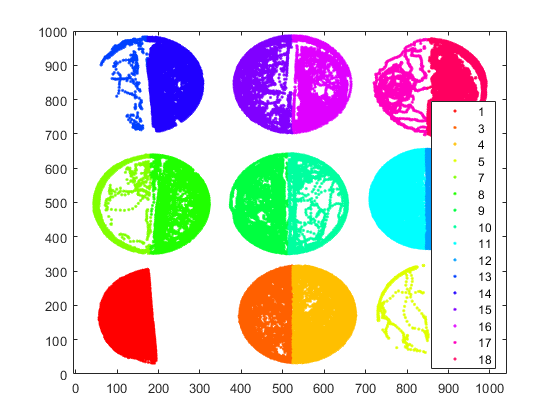


%Convert to table
T = array2table(out);

%Remove NaNs
T=T(~any(ismissing(T),2),:);

gscatter(T.out1, T.out2, T.out3)

%counting the number of traces in each region, and calculating AIs. As each
%AI is comparing the two halves of each circle, the AI for one half is
%always the negative value of the other half.
GC = groupcounts(T,'out3');
C1 = table2array(GC(1,2));

C2 = 0

C2 = table2array(GC(2,2));
C3 = table2array(GC(3,2));
C4 = table2array(GC(4,2));
C5 = table2array(GC(5,2));
C6 = table2array(GC(6,2));

C6 = 0

C7 = table2array(GC(7,2));
C8 = table2array(GC(8,2));
C9 = table2array(GC(9,2));
C10 = table2array(GC(10,2));
C11= table2array(GC(11,2));
C12 = table2array(GC(12,2));
C13 = table2array(GC(13,2));
C14 = table2array(GC(14,2));
C15 = table2array(GC(15,2));
C16 = table2array(GC(16,2));
C17 = table2array(GC(17,2));
C18 = table2array(GC(18,2));

AI1=(C1-C2)/(C1+C2)

AI1 = 1

AI2=(C2-C1)/(C1+C2)

AI2 = -1

AI3=(C3-C4)/(C3+C4)

AI3 = 0.0211

AI4=(C4-C3)/(C3+C4)

AI4 = -0.0211

AI5=(C5-C6)/(C5+C6)

AI5 = 1

AI6=(C6-C5)/(C5+C6)

AI6 = -1

AI7=(C7-C8)/(C7+C8)

AI7 = -0.4369

AI8=(C8-C7)/(C7+C8)

AI8 = 0.4369

AI9=(C9-C10)/(C9+C10)

AI9 = 0.7469

AI10=(C10-C9)/(C9+C10)

AI10 = -0.7469

AI11=(C11-C12)/(C11+C12)

AI11 = 0.8039

AI12=(C12-C11)/(C11+C12)

AI12 = -0.8039

AI13=(C13-C14)/(C13+C14)

AI13 = -0.5233

AI14=(C14-C13)/(C13+C14)

AI14 = 0.5233

AI15=(C15-C16)/(C15+C16)

AI15 = 0.7109

AI16=(C16-C15)/(C15+C16)

AI16 = -0.7109

AI17=(C17-C18)/(C17+C18)

AI17 = -0.9373

AI18=(C18-C17)/(C17+C18)

AI18 = 0.9373